close all;
clear

Caricamento o creazione dei dati.

% Caricamento
load data/ws_pca_esplorativa.mat


% Creazione
%{
s1=imread('img/steak01.jpg');    % 348x500x3  (3 matrici di pixel, una per channel)
s2=imread('img/steak02.jpg');

s1_unf= double(reshape(s1,348*500,3));    % 174000x3 (3 vettorei colonna, uno per channel)
s2_unf = double(reshape(s2,341*431,3));
%}

Visualizzo le due immagini di carne del mio dataset.

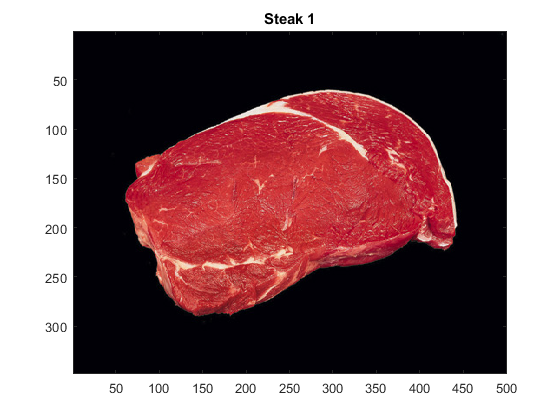

figure
imagesc(s1)
title("Steak 1")

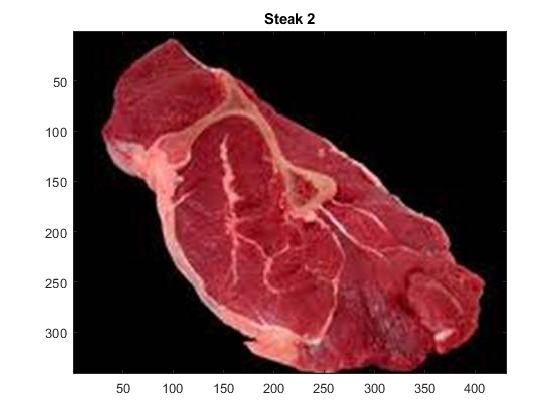


figure
imagesc(s2)
title("Steak 2")


%set(gcf, 'Position', get(gcf, 'Position')+[0 0 1900 500])

Viasulizzo la prima immagine andando a selezionare un canale per volta e poi 

creo l'istogramma dei canali.

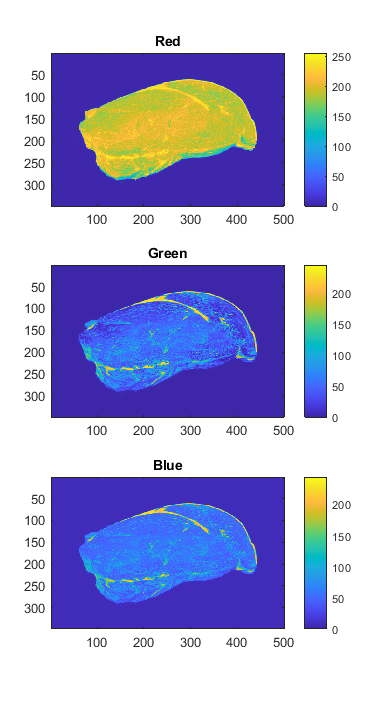

figure
for i=1:3
    subplot(3,1,i)
    imagesc(s1(:,:,i))  % seleziono solo l' i-esimo canale
    if i == 1
        title("Red")
    elseif i == 2
        title("Green")
    else
        title("Blue")
    end
    colorbar
end
set(gcf, 'Position', get(gcf, 'Position')+[0 0 500 1500])

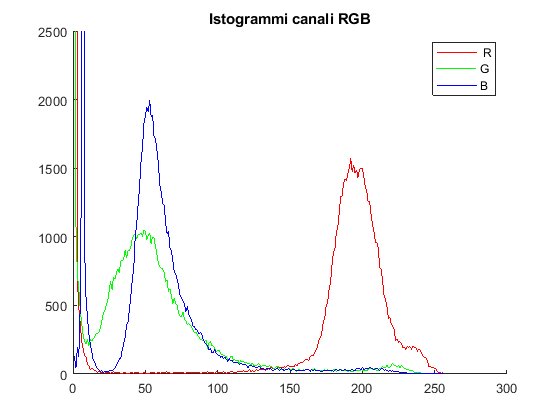


% Ist. RGB
figure
hold on
    plot(imhist(s1(:,:,1)),'r')
    plot(imhist(s1(:,:,2)),'g')
    plot(imhist(s1(:,:,3)),'b')
hold off
ylim([0,2500])
legend(' R','G','B');
title("Istogrammi canali RGB")

%set(gca, 'Yscale', 'log')       % display log scale?

trasformo immagine in bianco e nero e poi visualizzo l'istogramma dei pixel.

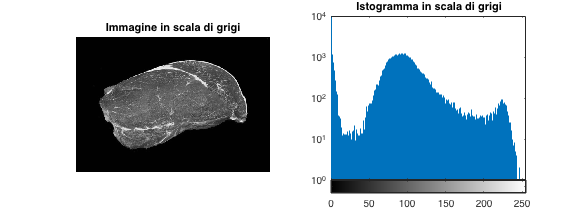

% Istogramma in scala di grigi
figure

subplot(1,2,1)
imshow(rgb2gray(s1))
title('Immagine in scala di grigi')

subplot(1,2,2)
imhist(rgb2gray(s1))
ylim([0,10000])
title('Istogramma in scala di grigi')

set(gcf, 'Position', get(gcf, 'Position')+[0 0 1900 500])
set(gca, 'Yscale', 'log')

Mostro la correlazione tra i canali R,G e B

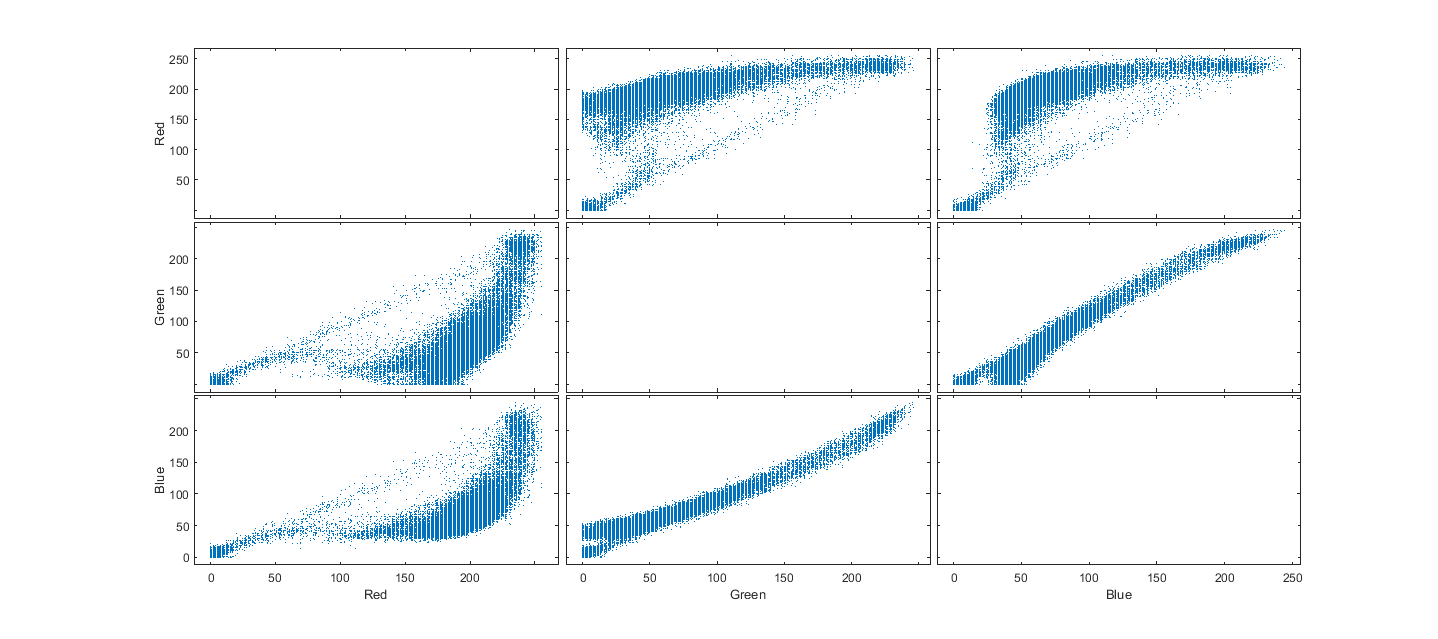

%cr = corrcoef(s1_unf)
gplotmatrix(s1_unf, [], {}, lines(3), [], [], [], 'none', {'Red','Green', 'Blue'})

Da PLS_Toolbox fare PCA esplorativa.

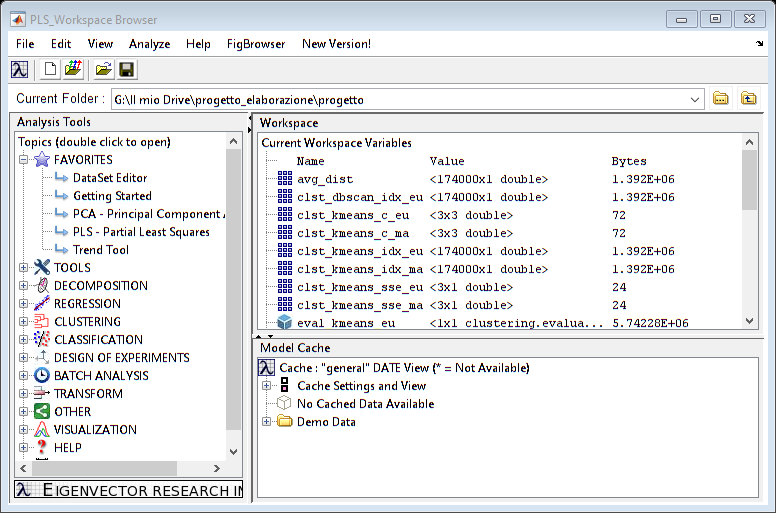

browse

Salvataggio dati della PCA nel workspace.

% Da PLS_Toolbox selezionare PC3 e fare review scores
% Dopo salvare il workspace con nome PC_scores
% Poi rinominare gli score di PC1, PC2 e PC3 come scritto di seguito
% Fai la stessa cosa per i loadings

%pc1_score = PC_scores.('Scores on PC 1').data
%pc2_score = PC_scores.('Scores on PC 2').data
%pc3_score = PC_scores.('Scores on PC 3').data
%clear PC_scores

%pc1_loading = PC_loadings.('PC 1').data
%clear PC_loadings

Visualizza sottoforma di immagini gli score della PCA.

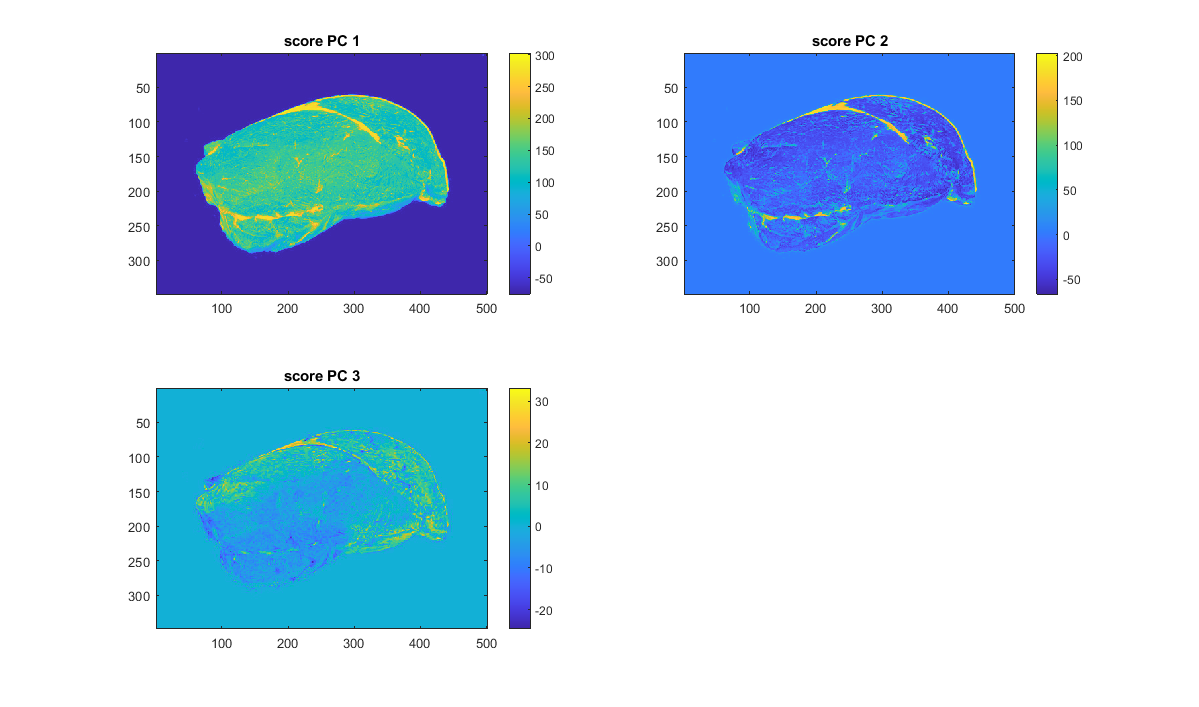

figure
subplot(2,2,1)
imagesc(reshape(pc1_score(:,1), 348, 500, 1))
colorbar
title('score PC 1')
subplot(2,2,2)
imagesc(reshape(pc2_score(:,1), 348, 500, 1))
colorbar
title('score PC 2')
subplot(2,2,3)
imagesc(reshape(pc3_score(:,1), 348, 500, 1))
colorbar
title('score PC 3')

set(gcf, 'Position', get(gcf, 'Position')+[0 0 1000 500])

Printa i loadings in riferimento alla PC1.

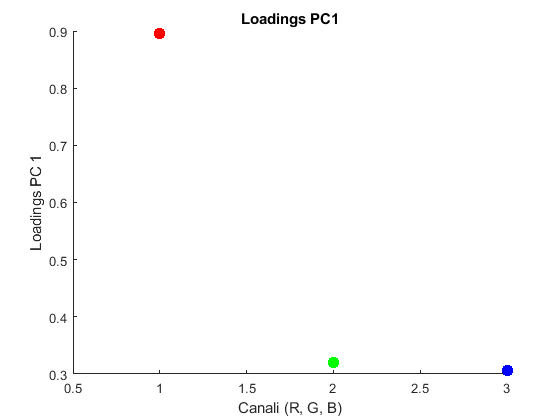

figure
hold on;
xlim([0.5, 3]);
scatter(1, pc1_loading(1,1),80, 'red', 'filled');
scatter(2, pc1_loading(2,1), 80, 'green', 'filled');
scatter(3, pc1_loading(3,1), 80, 'blue', 'filled');
xlabel('Canali (R, G, B)');
ylabel('Loadings PC 1');
title('Loadings PC1');

Istogramma degli score per capire come definire un threshold per la separazione di sfondo / carne / grasso

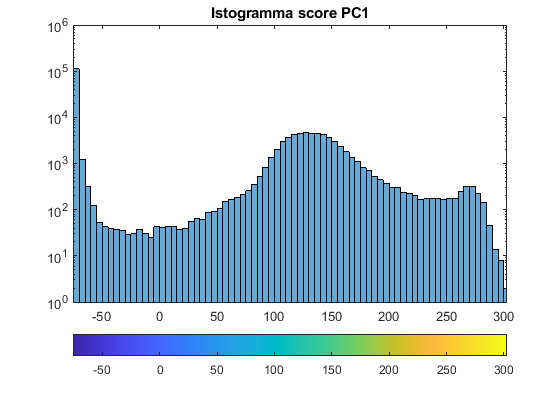

figure
%histogram2(randn(5000), randn(5000), "DisplayStyle","tile")
histogram(pc1_score)
%ylim([0,10])
xlim([min(pc1_score), max(pc1_score)])
set(gca, 'Yscale', 'log')
title('Istogramma score PC1')
colorbar('southoutside')
caxis([min(pc1_score), max(pc1_score)])

Immagine R,G,B colorata a partire dai valori di PC1 a cui applico il threshold scelto.

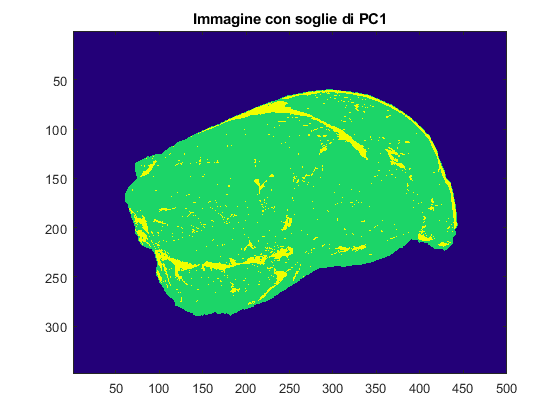

% pca_img_threshold NON è UNFOLDED!! E' 174000x3
pca_img_threshold = uint8(zeros(length(pc1_score), 3));

for i = 1:length(pc1_score)
    if pc1_score(i,1) <= 0
        % Sfondo
        pca_img_threshold(i,1) = 35;
        pca_img_threshold(i,2) = 0;
        pca_img_threshold(i,3) = 120;   
    elseif pc1_score(i,1) >= 185
        % Grasso
        pca_img_threshold(i,1) = 240;
        pca_img_threshold(i,2) = 255;
        pca_img_threshold(i,3) = 0;   
    else
        % Carne
        pca_img_threshold(i,1) = 28;
        pca_img_threshold(i,2) = 213;
        pca_img_threshold(i,3) = 104;        
    end
end

figure
imagesc(reshape(pca_img_threshold, 348, 500, 3))
title("Immagine con soglie di PC1")

CLUSTERING

Visualizzo i dati in 3 dimensioni considerando come colore quello corrispondente alla PC1

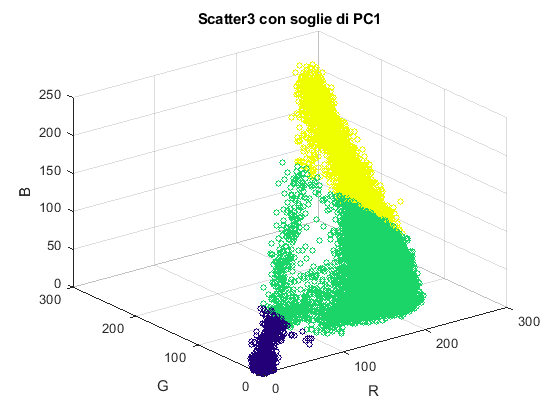

figure
scatter3(s1_unf(:,1), s1_unf(:,2), s1_unf(:,3), 15, mat2gray(pca_img_threshold))
title("Scatter3 con soglie di PC1");
xlabel("R");
ylabel("G");
zlabel("B");

%hold on
%h = gobjects(3,1);
%h(1) = scatter3([0 0], [0 0], [0 0], 1, mat2gray([35 0 120]));
%h(2) = scatter3([0 0], [0 0], [0 0], 1, mat2gray([28 213 104]));
%h(3) = scatter3([0 0], [0 0], [0 0], 1, mat2gray([240 255 0]));
%legend(h, {'Sfondo', 'Carne', 'Grasso'});

KMEANS

Calcolo il cluster con kmeans cambiando diversi parametri.

% Euclidean
[clst_kmeans_idx_eu, clst_kmeans_c_eu, clst_kmeans_sse_eu] = kmeans(s1_unf, 3, "Distance","sqeuclidean");
clst_kmeans_idx_eu = adjust_cluster_idx(clst_kmeans_idx_eu);

% Manhattan
[clst_kmeans_idx_ma, clst_kmeans_c_ma, clst_kmeans_sse_ma] = kmeans(s1_unf, 3, "Distance","cityblock");
clst_kmeans_idx_ma = adjust_cluster_idx(clst_kmeans_idx_ma);

Print scatter 3d e immagine con pixel colorati per cluster.

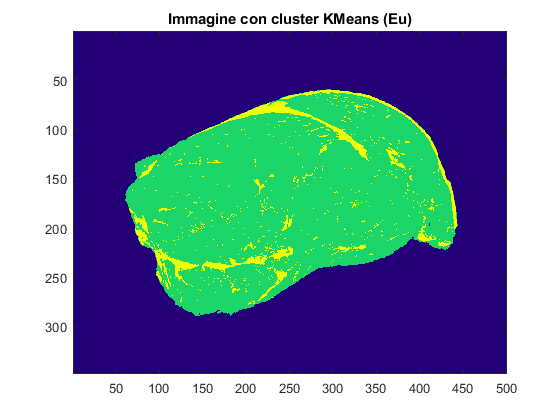

figure
color_cluster = mat2gray(print_img_from_cluster_idx(clst_kmeans_idx_eu));
title('Immagine con cluster KMeans (Eu)');

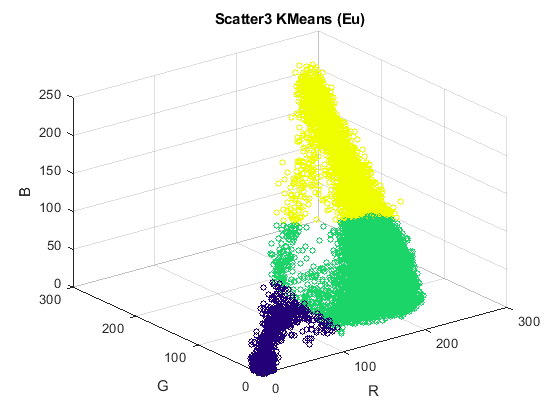

scatter3(s1_unf(:,1), s1_unf(:,2), s1_unf(:,3), 15, color_cluster)
title("Scatter3 KMeans (Eu)");
xlabel("R");
ylabel("G");
zlabel("B");

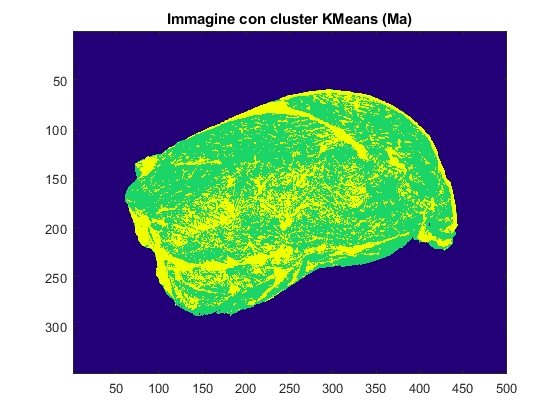


figure
color_cluster = mat2gray(print_img_from_cluster_idx(clst_kmeans_idx_ma));
title('Immagine con cluster KMeans (Ma)');

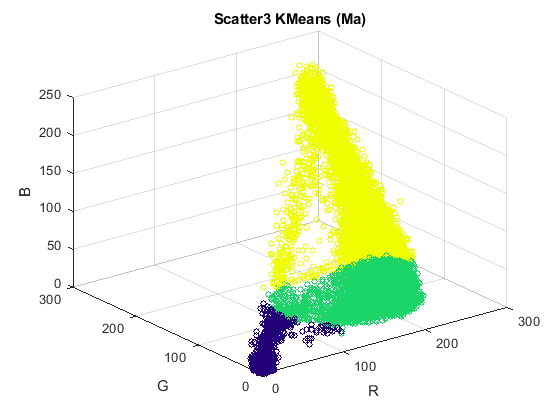

scatter3(s1_unf(:,1), s1_unf(:,2), s1_unf(:,3), 15, color_cluster)
title("Scatter3 KMeans (Ma)");
xlabel("R");
ylabel("G");
zlabel("B");


clear color_cluster

Salvate nel workspace perchè fare l'eval richiede tempo.

%eval_kmeans_eu = evalclusters(s1_unf, "kmeans", "silhouette", "KList", 3, "Distance", "sqEuclidean");

%eval_kmeans_ma = evalclusters(s1_unf, "kmeans", "silhouette", "KList", 3, "Distance", "cityblock");

Valutazione K-Means con Silhouette score. 

Vedi se fare anche SSE con grafico che plotta SSE in funzione del numero di cluster.

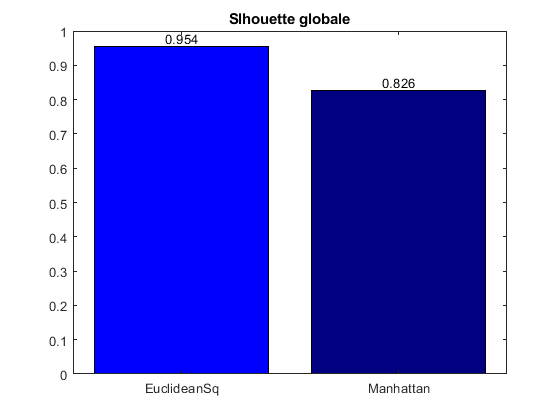

% Silhouette generale 
figure
b = bar(categorical({'EuclideanSq'; 'Manhattan'}), ...
    [eval_kmeans_eu.CriterionValues, ...
    eval_kmeans_ma.CriterionValues]);
b.FaceColor = "flat";
b.CData(1,:) = [0 0 1];
b.CData(2,:) = [0 0 0.5];
text(b(1).XEndPoints, b(1).YEndPoints, string(round(b(1).YData*100,1)/100), "HorizontalAlignment","center","VerticalAlignment","bottom");
title("Slhouette globale");

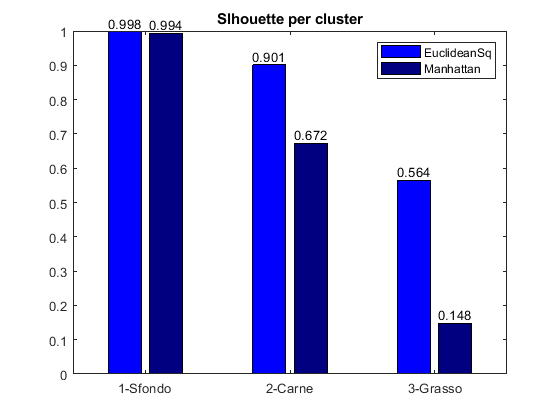


% Silhouette per cluster (può essere che l'eval riporti i silhouette
% in maniera non ordinata quindi li riordino)
figure
b = bar(categorical({'1-Sfondo'; '2-Carne'; '3-Grasso'}), ...
    [sort([eval_kmeans_eu.ClusterSilhouettes{1,:}]', 'descend'); ...
     sort([eval_kmeans_ma.ClusterSilhouettes{1,:}]', 'descend')]);
b(1).FaceColor = [0 0 1];
b(2).FaceColor = [0 0 0.5];
text(b(1).XEndPoints, b(1).YEndPoints, string(round(b(1).YData*100,1)/100), "HorizontalAlignment","center","VerticalAlignment","bottom");
text(b(2).XEndPoints, b(2).YEndPoints, string(round(b(2).YData*100,1)/100), "HorizontalAlignment","center","VerticalAlignment","bottom");
title("Slhouette per cluster");
legend({'EuclideanSq', 'Manhattan'});


clear b

DBSCAN

I parametri sono stati impostati nel seguente modo:

- min_pts : 2 * dimensionalità (quindi 2*3=6)

- eps : sono state guardate le distanze medie di ogni punto dai suoi 6 punti più vicini nel dataset. Queste sono state riordinate e messe su grafico. eps è scelto come quel punto in cui il grafico sale (2 oppure 3). 

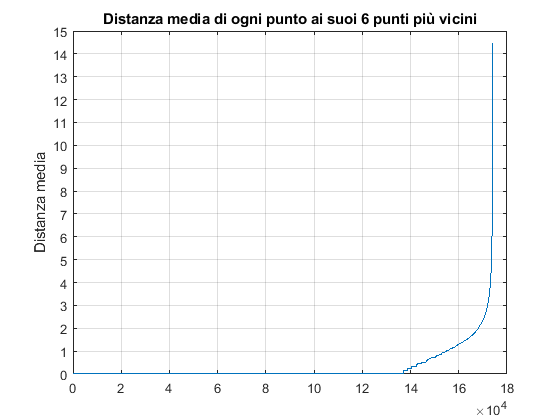

%kdtree_searcher = KDTreeSearcher(s1_unf);
%[idx_search, dist_search] = knnsearch(kdtree_searcher, s1_unf, 'k', 6);
%avg_dist = sort(mean(dist_search, 2));

figure
plot(avg_dist);
ylabel("Distanza media");
grid
yticks([0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15])

title("Distanza media di ogni punto ai suoi 6 punti più vicini")

clear kdtree_searcher
clear idx_search
clear dist_search

% epsilon = 2
%clst_dbscan_idx_eu_2 = dbscan(s1_unf, 2, 6);
%clst_dbscan_idx_eu_2 = clst_dbscan_idx_eu_2';
%unique(clst_dbscan_idx_eu_2);

%unique(clst_dbscan_idx_eu)

ans = 173628

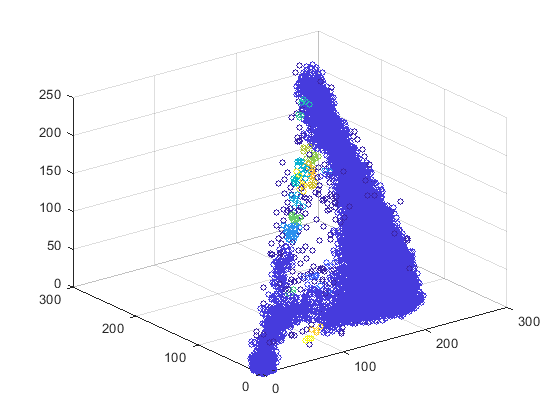

sum(clst_dbscan_idx_eu_2==1)
figure

scatter3(s1_unf(:,1), s1_unf(:,2), s1_unf(:,3), 15, clst_dbscan_idx_eu_2)

PREDIZIONE GRASSO CON PCA

1) Creazione PCA con i soli pixel del grasso trovati tramite cluster KMeans

2) Utilizzare modello PCA creato per capire quali pixel di un'immagine mai vista (img2) sono grasso

Di seguito ricavo i pixel del grasso travti dal KMeans per poi fare PCA

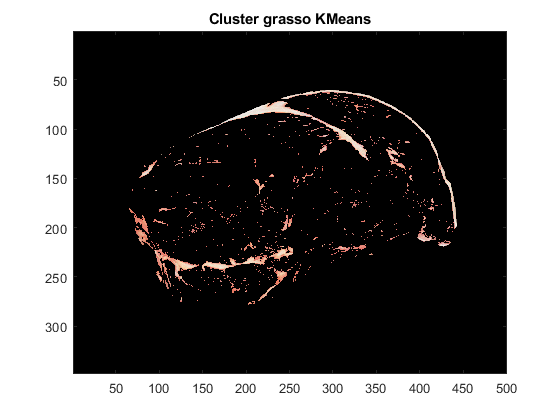

fat_unf = get_fat_from_cluster_idx(s1_unf, clst_kmeans_idx_eu);
print_fat_from_cluster_idx(clst_kmeans_idx_eu, s1_unf);
title("Cluster grasso KMeans");

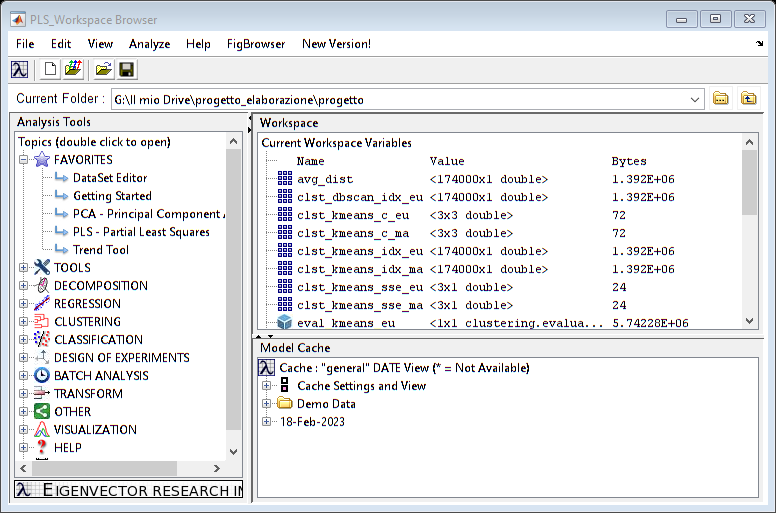

%browse

Salvataggio dati PCA nel workspace

pc1_pred_q = pca_pred.('Q Residuals').data;
pc1_pred_t2 = pca_pred.('Hotelling T^2').data;
pc1_pred_scores = pca_pred.('Scores on PC 1').data;
%clear pca_pred;

%pc1_fat_loading = pc1_fat_loading_.('PC 1').data;
%clear pc1_fat_loading_;

t2_limit = cell2array(pca_pred_model.detail.tsqlim);
q_limit = cell2array(pca_pred_model.detail.reslim);

Print loadings della PCA

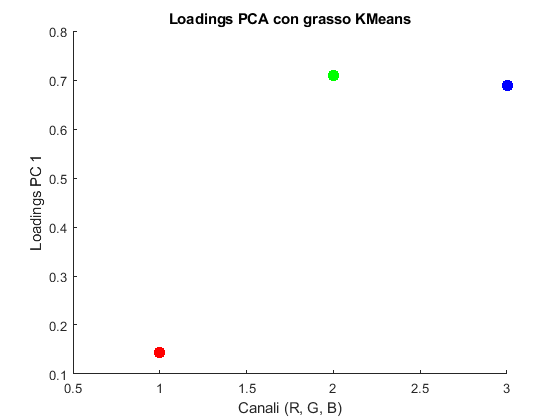

figure
hold on;
xlim([0.5, 3]);
scatter(1, pc1_fat_loading(1,1),80, 'red', 'filled');
scatter(2, pc1_fat_loading(2,1), 80, 'green', 'filled');
scatter(3, pc1_fat_loading(3,1), 80, 'blue', 'filled');
xlabel('Canali (R, G, B)');
ylabel('Loadings PC 1');
title('Loadings PCA con grasso KMeans');

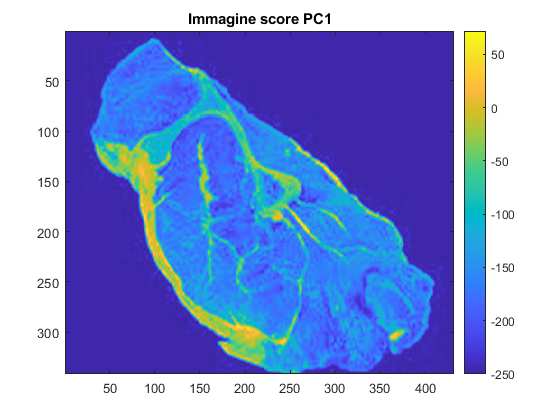


figure
imagesc(reshape(pc1_pred_scores(:,1), 341, 431, 1))
colorbar
title('Immagine score PC1');

Visualizzo i pixel accettati con t<t2_lim e q<qlim in riferimento a steak2.

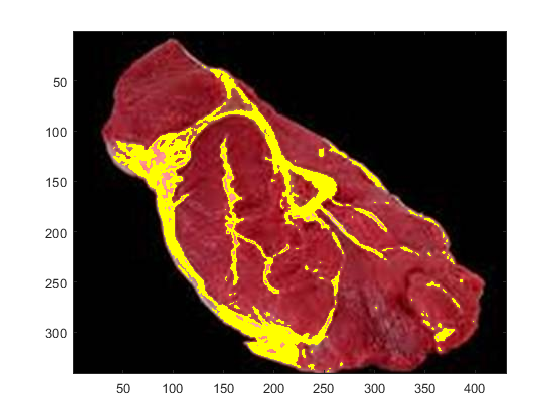

fat_pred_img = uint8(zeros(length(s2_unf), 3));

for j=1:length(s2_unf)
    if (pc1_pred_t2(j) < t2_limit) && (pc1_pred_q(j) < q_limit)
        fat_pred_img(j,1) = 255;
        fat_pred_img(j,2) = 255;
        fat_pred_img(j,3) = 0;
    else
        fat_pred_img(j,1) = s2_unf(j, 1);
        fat_pred_img(j,2) = s2_unf(j, 2);
        fat_pred_img(j,3) = s2_unf(j, 3);
    end
end

figure
imagesc(reshape(fat_pred_img, 341, 431, 3));


clear fat_pred_img;

function res = print_img_from_cluster_idx(idx)
    % questi valori funzionano solamente se le classi sono:
    % classe 1 : sfondo
    % classe 2 : carne
    %classe 3 : grasso
    kmeans_img = uint8(zeros(length(idx), 3));
    
    for j = 1:length(idx)
        if idx(j) == 1
            % sfondo
            kmeans_img(j, 1) = 35;
            kmeans_img(j, 2) = 0;
            kmeans_img(j, 3) = 120;
        elseif idx(j) == 2
            % carne
            kmeans_img(j, 1) = 28;
            kmeans_img(j, 2) = 213;
            kmeans_img(j, 3) = 104; 
        elseif idx(j) == 3
            %grasso
            kmeans_img(j, 1) = 240;
            kmeans_img(j, 2) = 255;
            kmeans_img(j, 3) = 0;
        end
    end
    
    figure
    imagesc(reshape(kmeans_img, 348, 500, 3))
    
    res = kmeans_img;
    
    clear j

end


function res = print_fat_from_cluster_idx(idx, img_unf)
    % questi valori funzionano solamente se le classi sono:
    % classe 1 : sfondo
    % classe 2 : carne
    %classe 3 : grasso
    kmeans_img = uint8(zeros(length(idx), 3));
    
    for j = 1:length(idx)
        if idx(j) == 3
            %grasso
            kmeans_img(j, 1) = img_unf(j, 1);
            kmeans_img(j, 2) = img_unf(j, 2);
            kmeans_img(j, 3) = img_unf(j, 3);
        else
            kmeans_img(j, 1) = 0;
            kmeans_img(j, 2) = 0;
            kmeans_img(j, 3) = 0;           
        end
    end
    
    figure
    imagesc(reshape(kmeans_img, 348, 500, 3))
    
    res = kmeans_img;
    
    clear j

end


function res = adjust_cluster_idx(idx)
    % Uniforma i cluster id : 
    %   1 : sfondo
    %   2 : carne
    %   3 : grasso
    % containers fa in automatico un sort per le chiavi
    % (numero di occorrenze) e poi imposto come valori [1,2,3]
    r = values(containers.Map({sum(idx == 1), ...
        sum(idx == 2), ...
        sum(idx == 3)}, ...
        [1,2,3]));
    new_val = flip([r{1,:}]');
    
    for j = 1:length(idx)
        idx(j) = find(new_val==idx(j));
    end
    
    res = idx;
    
    clear r
    clear new_val
end



function res = get_fat_from_cluster_idx(img_unf, idx)
    % Ritorna i pixel (rgb) in formato unfolded in riferimento
    % alla classe grasso (3) ritornata dal cluster
    fat_unf = double(zeros(sum(idx == 3), 3));
    fat_count = 1;
    
    for j = 1:length(idx)
        if idx(j) == 3
            fat_unf(fat_count, 1) = img_unf(j, 1);
            fat_unf(fat_count, 2) = img_unf(j, 2);
            fat_unf(fat_count, 3) = img_unf(j, 3);
            
            fat_count = fat_count + 1;
        end
    end
    
    res = fat_unf;
    
end
